
clc;clear allvars;
g = 9.81;
y = 63;
mu0 = 4*pi*10e-7;
I = 10;
a = 3;
A = 2*pi*a*3;
L = 63;

T = 0:0.1:sqrt(2*y/g);

syms t 
B = ( mu0.*I.*a.^2 )/( 2*(a.^2 + ((g.^2 * t.^4)./4)).^(3/2) );
dB = diff(B);
fem = -A*dB

$$fem = \frac{1645599280878130113\,t^{3}\,\pi^{2}}{3518437208883200000\,{\left(\frac{6772013501556091\,t^{4}}{281474976710656}+9\right)}^{5/2}}$$

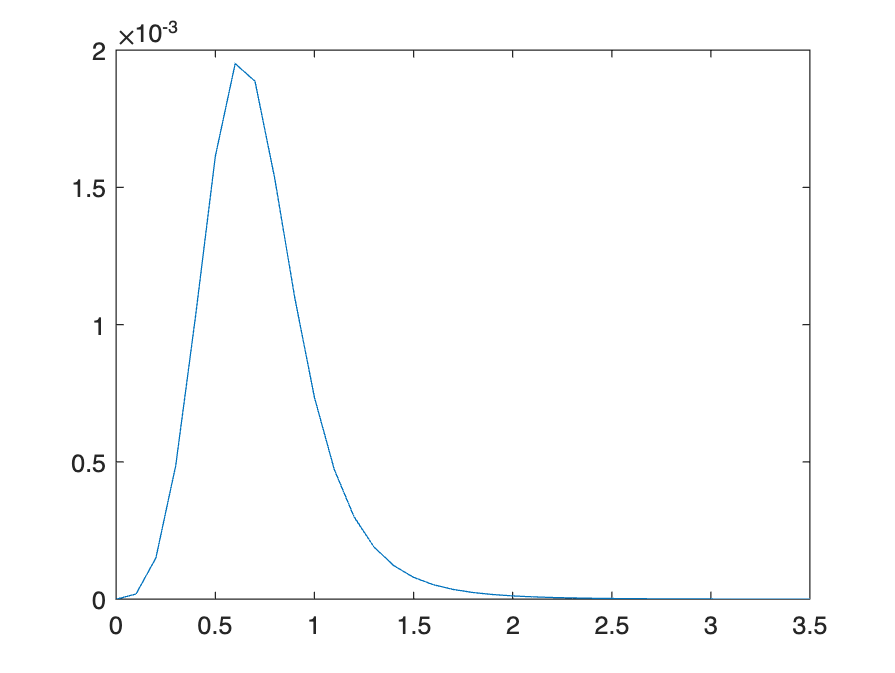

misFems = vpa(subs(fem,t,T));
plot(T,misFems)